# Creating and Training a CNN to Classify Traffic Signs

For the Week 1 Project, you will:

- Prepare the traffic signs dataset for training

- Create a simple CNN

- Train the model to classify traffic signs

- Evaluate your trained model on test data

After you have finished, please proceed to the **"Project: Classifying Traffic Signs with a Simple CNN" **assessment to answer questions about your results.

## Prepare Your Data for Training

Inside the "Traffic Signs" folder, the data is already separated into Train and Test folders. 

Create an image datastore from the training dataset named `imdsSigns`:

% Select the location of the training data set:
filename = "E:\Semester Pendek\MATLAB\Deep Learning for Computer Vision\Data\Traffic Signs\Train";
imdsSigns = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames")

imdsSigns =   ImageDatastore with properties:

                       Files: {
                              ' ...\Data\Traffic Signs\Train\End Speed Limit\sign0003.png';
                              ' ...\Data\Traffic Signs\Train\End Speed Limit\sign0006.png';
                              ' ...\Data\Traffic Signs\Train\End Speed Limit\sign0011.png'
                               ... and 897 more
                              }
                     Folders: {
                              ' ...\MATLAB\Deep Learning for Computer Vision\Data\Traffic Signs\Train'
                              }
                      Labels: [End Speed Limit; End Speed Limit; End Speed Limit ... and 897 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                 

Use 80% of your data for training, leaving the remaining images for validation. Make sure to randomize which images are assigned to the validation set.

[imdsSigns,imdsValidation] = splitEachLabel(imdsFasteners,0.8,"randomized");


## Preview the Training Data

Before you dive into building your network architecture, it's worth familiarizing yourself with the images in this data set. 

Run this section several times to preview some of the training data:

img = read(imdsSigns);
size(img)

ans =     32    32     3


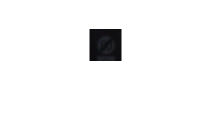

imshow(img)

Notice how many of the images are small, dark, blury, or otherwise difficult to see. 

All images are in RGB format, with sizes  $m \times n \times 3$, but they have a range of different sizes. Before you can train, you will have to resize these images to match the image input layer.

## Define the Network Architecture

The following code will open the Deep Network Designer App. Use the app to create and export a network with the following layers:

- `imageInputLayer`

- `convolution2dLayer`

- `reluLayer `

- `maxPooling2dLayer`

- `fullyConnectedLayer`

- `softmaxLayer`

- `classificationLayer`

Make sure you specify the correct `OutputSize` for `fullyConnectedLayer`.

if isMATLABReleaseOlderThan("R2024a")
    deepNetworkDesigner
else
    deepNetworkDesigner -v1
end

layers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(9,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];



## Resize Your Training Data

Resize the training and validation data to match the `InputSize` that you set above:

augTrain = augmentedImageDatastore([227,227],imdsSigns);
augVal = augmentedImageDatastore([227,227],imdsValidation);


## Setting the Training Options

Finally, set your training options. You'll investigate training options in more detail later in this course. For now, use the same options as you saw in the video:

- Set the solver to `"adam"`

- Include the validation data you set aside earlier

- Set the Shuffle option to `"every-epoch"`

- Set the Plots option to `"training-progress"`

opts = trainingOptions("adam","ValidationData",augVal,"Shuffle",...
    "every-epoch","Plots","training-progress");


## Train the Network

It's finally time to train your network! 

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:40 |       13.28% |       17.78% |      31.7954 |   11504.2178 |          0.0010 |
|      10 |          50 |       00:25:59 |       71.88% |       54.44% |     151.2962 |     329.7988 |          0.0010 |
|      20 |         100 |       00:45:17 |       92.19% |       63.33% |      12.3045 |     193.8501 |          0.0010 |
|      30 |         150 |       01:04:20 |       89.84% |       65.00% |      17.9840 |   

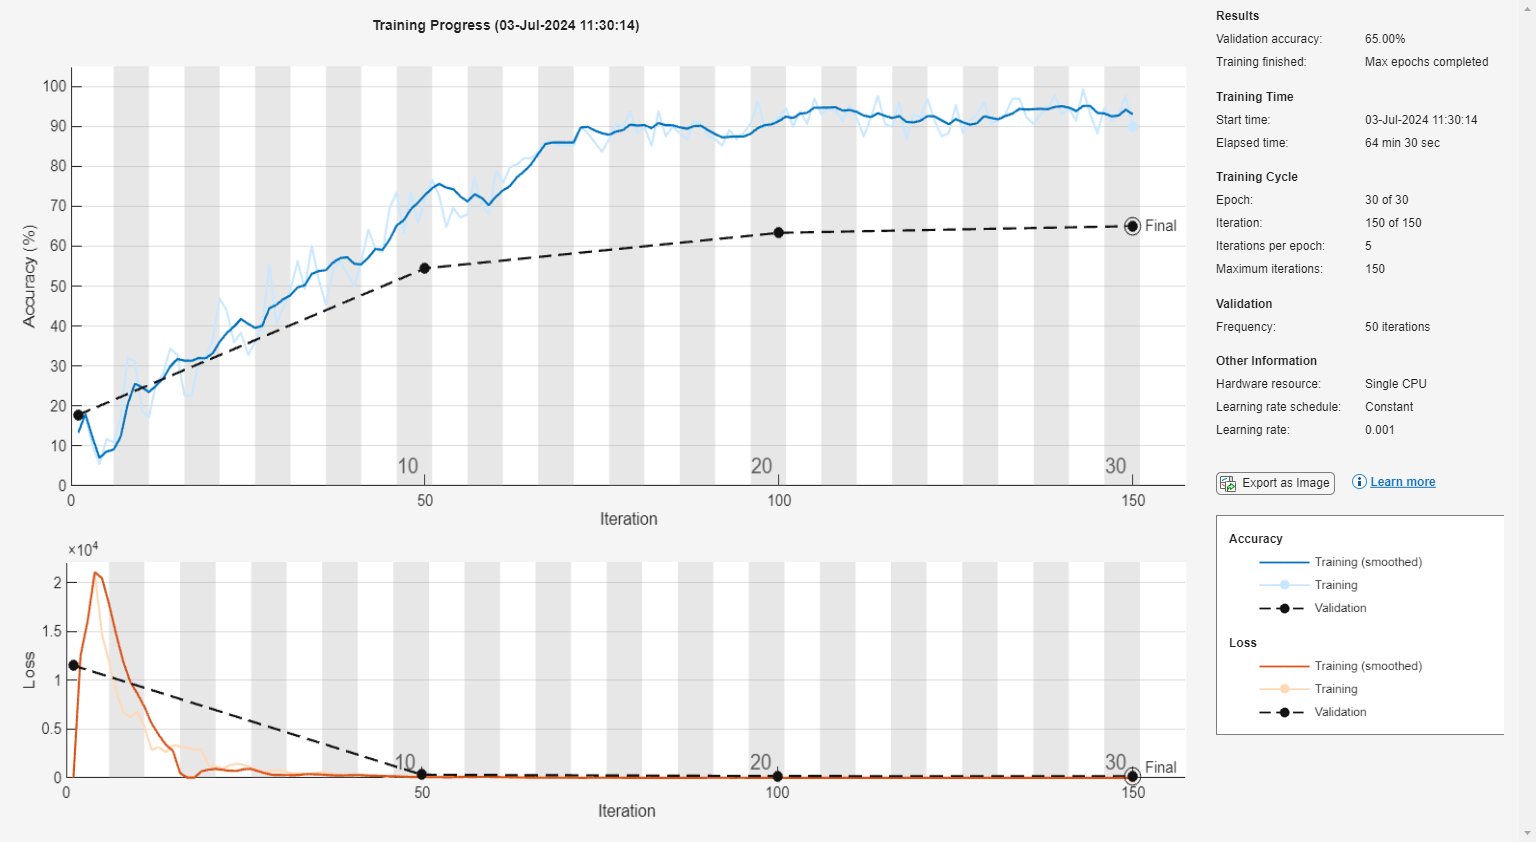

trainNew = true;
if trainNew
    net = trainNetwork(augTrain,layers,opts);
else
    load params_minggu_1.mat
end

Training will likely take about 20 minutes using a CPU.

## Performance on Test Data

Once you have trained your network, you should examine its performance on your test data.

Don't forget to resize your images to match the expected input size for your trained network:

filenameTest = "E:\Semester Pendek\MATLAB\Deep Learning for Computer Vision\Data\Traffic Signs\Test";
imdsTest = imageDatastore(filenameTest,"IncludeSubfolders",true,"LabelSource","foldernames");


Finally, use your test data to evaluate your trained network, including calculating the test accuracy and creating a confusion chart. You may need to click the arrow and open your confusion charts in the figure window to see them well:

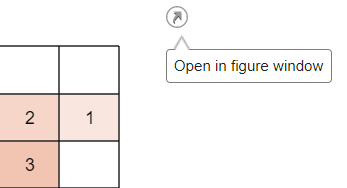

% Classify your test data:
augTest = augmentedImageDatastore([227,227],imdsTest);
testPreds = classify(net,augTest);

testAccuracy = nnz(testPreds == imdsTest.Labels)/length(testPreds)

testAccuracy = 0.6424

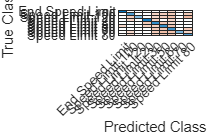

% Compute the test accuracy and create a confusion chart:

confusionchart(imdsTest.Labels,testPreds)

While not perfect, this network performs surprisingly well considering the limited data set and the relatively simple architecture of your neural network. Later in this course, you will see how to achieve much better accuracy and loss values for this dataset.

Once you have completed this reading, proceed to the "Week 1 Project: Classifying Traffic Signs with a Simple CNN" quiz. You may want to keep this completed live script open as a reference as you answer questions about your results.

*Copyright 2024 The MathWorks, Inc.*